Compreendendo campos vetorias:

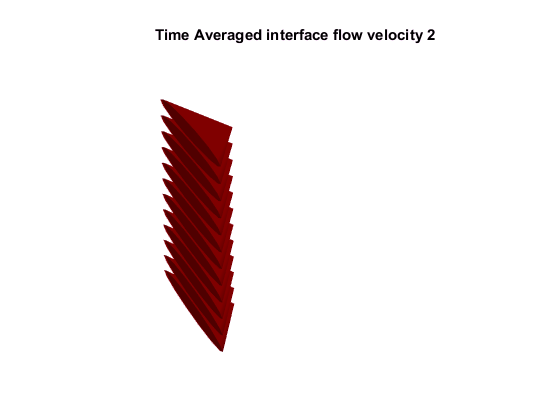

%% 3-D Cone Plot
% Plot velocity vector cones for vector volume data representing motion of
% air through a rectangular region of space.

% Copyright 2015 The MathWorks, Inc.


%% cria os vetores x,y,z que especificam as coordenadas
 
 x = zeros(12,2,12);
 y = x;
 z = ones(12,2,12);

 x(:,1,1) = ones(12,1);
 x(:,2,1) = 2 .* x(:,1,1);
 for count1 = 2 : 1 : 12
     x(:, :, count1) = x(:, :, 1);
 end
 
 y(:,1,1) = linspace(1,12,12)';
 y(:,2,1) = linspace(1,12,12)';
 for count2 = 2 : 1 :12
     y(:,:, count2) = y(:,:,1);
 end
 
 z(:,1,1) = ones(12,1);
 z(:,2,1) = z(:,1,1);
 for count3 = 2 : 1 : 12
     z(:, :, count3) = count3 .* z(:, : ,1);
 end
 
 
 
 
 
 
 
 %% Cria o espaço vetorial com as coordenadas dos vetores
 

%% Modifica;óes do Lu[is
x = x(1:12,1:2,1:12);
y=y(1:12,1:2,1:12);
z=z(1:12,1:2,1:12);
u=u(1:12,1:2,1:12);

u( 2:12 ,1:2,:) =0;

v=v(1:12,1:2,1:12);

v( 2:12 ,1:2,:) =0;

w=w(1:12,1:2,1:12);

w( 2:12 ,1:2,:) =0;

%%
% Calculate the magnitude of the vector field (which represents wind speed)
% to generate scalar data for the |slice| command.


wind_speed = sqrt(u.^2 + v.^2 + w.^2);




%% 
% Establish the range of the data to place the slice planes and to specify
% where you want the cone plots.

xmin = min(x(:));
xmax = max(x(:));
ymin = min(y(:));
ymax = max(y(:));
zmin = min(z(:));

%%
% Define where to plot the cones. Select the full range in |x| and |y| and
% select the range 3 to 15 in |z|.

xrange = linspace(xmin,xmax,1);
yrange = linspace(ymin,ymax,12);
zrange = 1:1:12;
[cx,cy,cz] = meshgrid(xrange,yrange,zrange);

%%
% Plot the cones and set the scale factor to 5 to make the cones larger
% than the default size. 

figure
hcone = coneplot(x,y,z,u,v,w,cx,cy,cz,2, wind_speed);

% hcone = coneplot(x,y,z,u,v,w,cx,cy,cz,2,'quiver');

%%
% Set the cone colors.

% hcone.FaceColor = 'red';
hcone.EdgeColor = 'none';



%%
% Change the axes view and set the data aspect ratio.

axis square
axis off

% view(30,40)
% daspect([2,2,1])

%%
% Add a light source to the right of the camera and use Gouraud lighting to
% give the cones and slice planes a smooth, three-dimensional appearance.

camlight right
lighting gouraud
% set(hsurfaces,'AmbientStrength',0.6)
%hcone.DiffuseStrength = 0.8;
view([72 20]);
camproj perspective;
camzoom(1.0);
axis off;
grid off;
box on;
light;
lighting phong;
camlight('left');
colormap jet
shading interp;

%% 
title('Time Averaged interface flow velocity 2') % Set the cone colors.